
% input are two variables, each consisting of the time points of the
% negative peak of the control and SE PSPs. Peaks are measured separately
% in AxoGraph.

control_neg_peaks = [];
SE_neg_peaks = [];


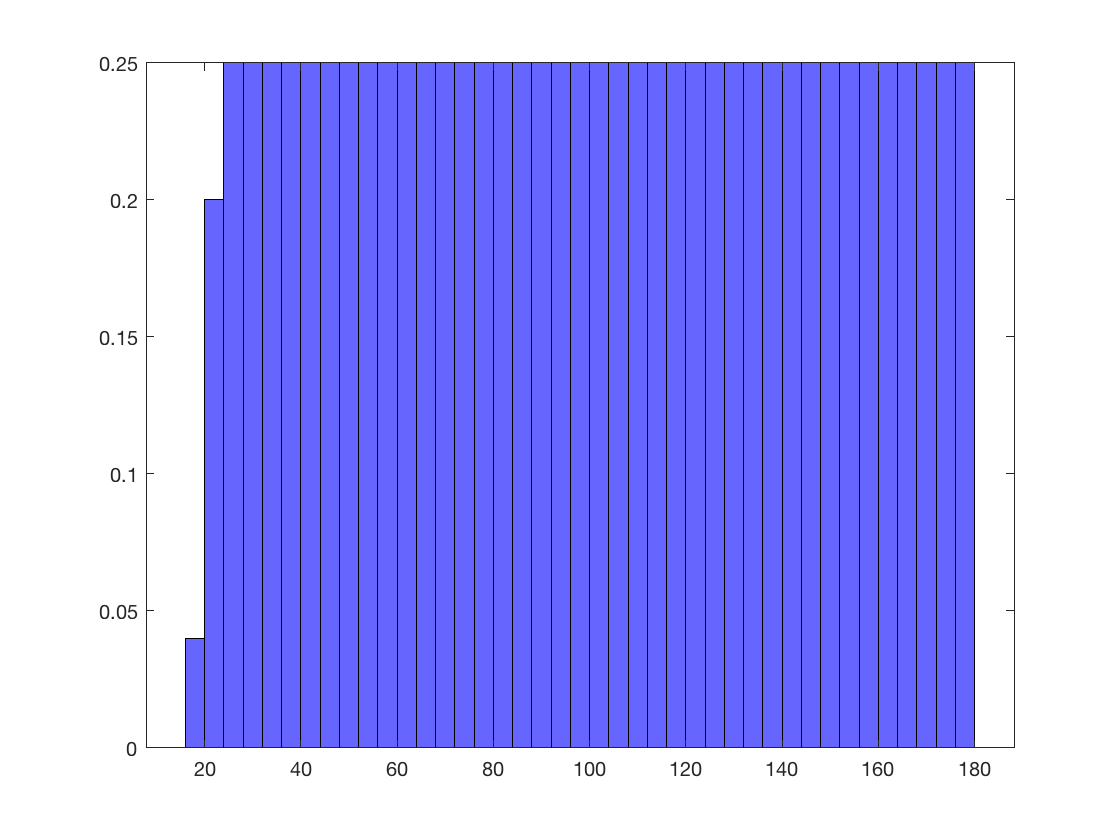

% compare negative peak time histograms for each group

figure;
h1 = histogram(control_neg_peaks,60,'facecolor',[0 0 1]);
h1.Normalization = 'cdf';
h1.BinWidth = 4;
ylim([0 0.25])

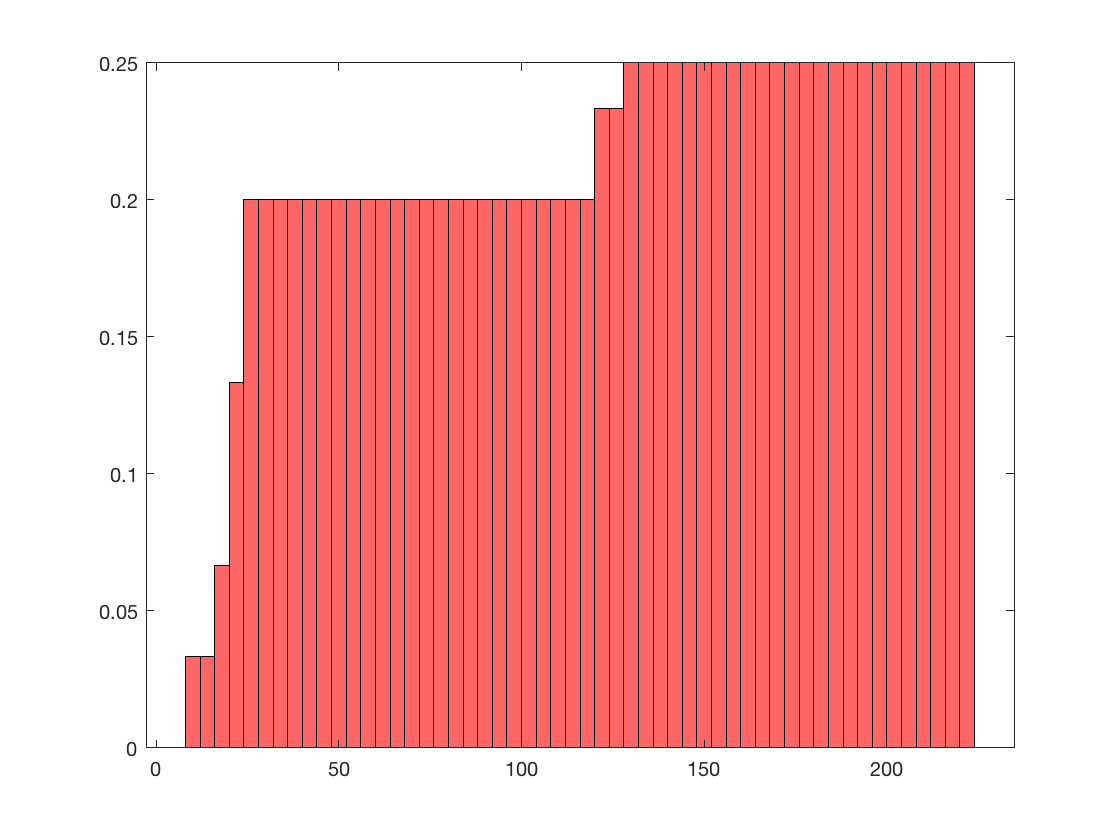



figure;
h2 = histogram(SE_neg_peaks,60,'facecolor','r');
h2.Normalization = 'cdf';
h2.BinWidth = 4;
ylim([0 0.25])

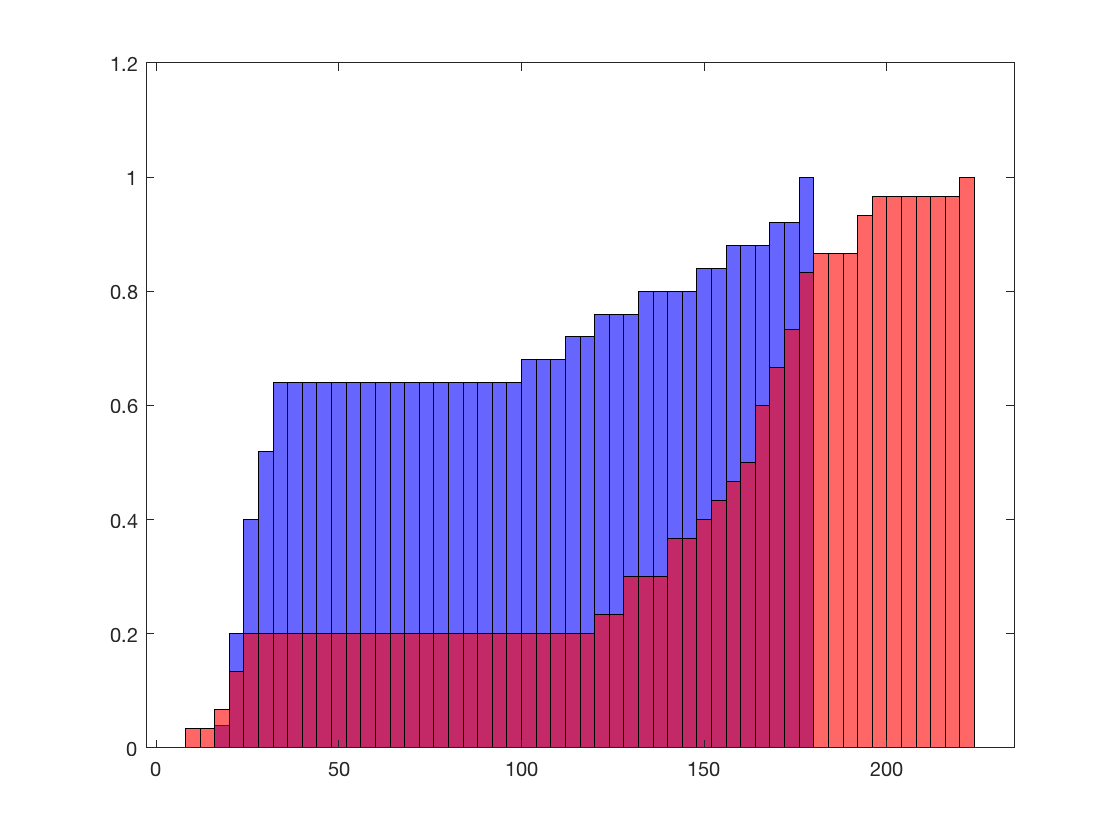


figure;
h3 = histogram(control_neg_peaks,60,'facecolor',[0 0 1]);
hold on
h4 = histogram(SE_neg_peaks,60,'facecolor',[1 0 0]);
h3.Normalization = 'cdf';
h3.BinWidth = 4;
h4.Normalization = 'cdf';
h4.BinWidth = 4;

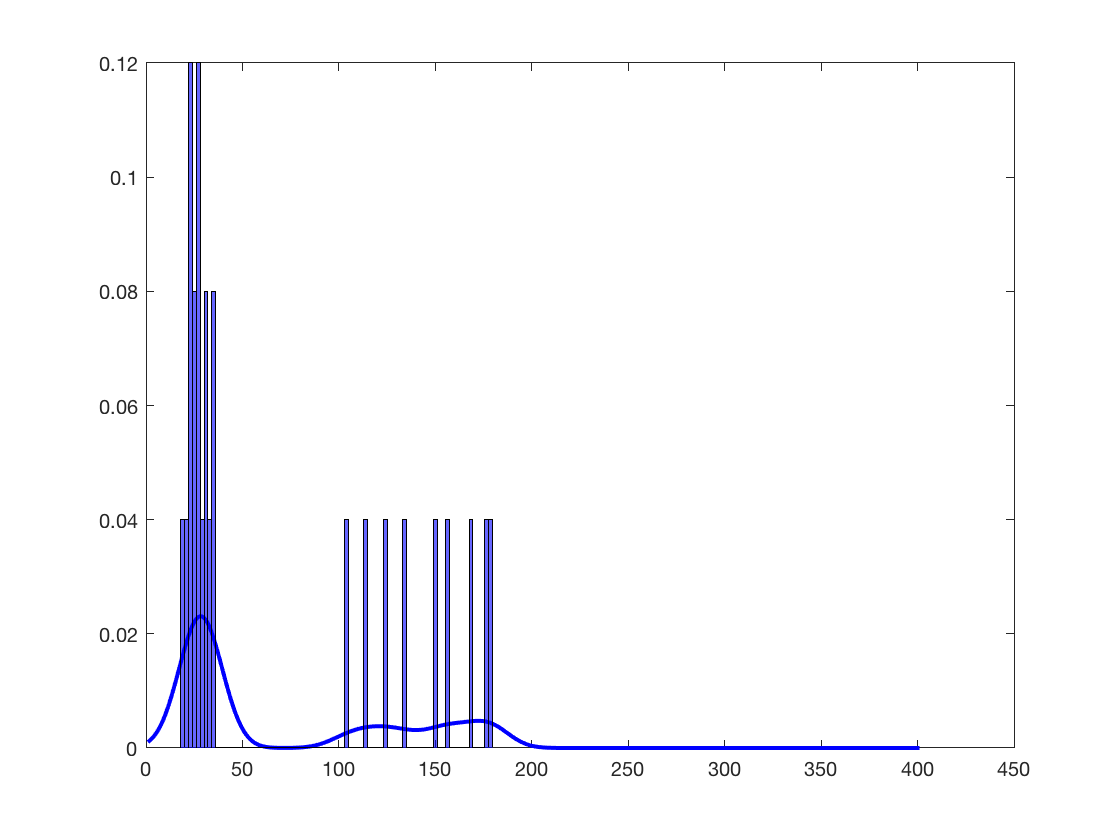

% fit a probability density function to each group

c = control_neg_peaks;

c_dist = fitdist(c,'Kernel','bandwidth',10);


x = 0:1:400;
c_pdf = pdf(c_dist,x);

figure;
plot(c_pdf,'color','b','LineWidth',2);
hold on
h3 = histogram(control_neg_peaks,80,'facecolor',[0 0 1]);
h3.Normalization = 'probability';

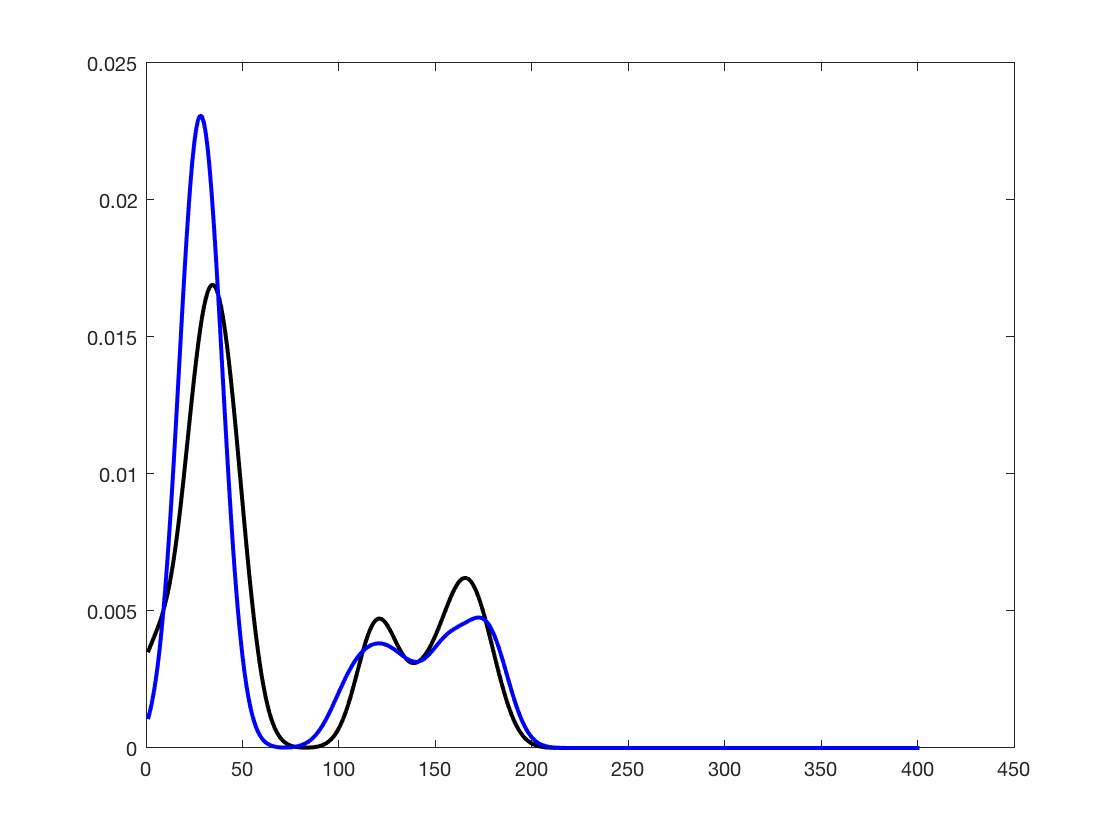



%

for i = 1:25;
b(i,:) = (c(i)+(rand*25)-(rand*25));
end

b_dist = fitdist(b,'Kernel','bandwidth',10);


x = 0:1:400;
b_pdf = pdf(b_dist,x);

figure;
plot(b_pdf,'color','k','LineWidth',2);
hold on
%h5 = histogram(b,60,'facecolor',[0 0 0]);
%h5.Normalization = 'probability';

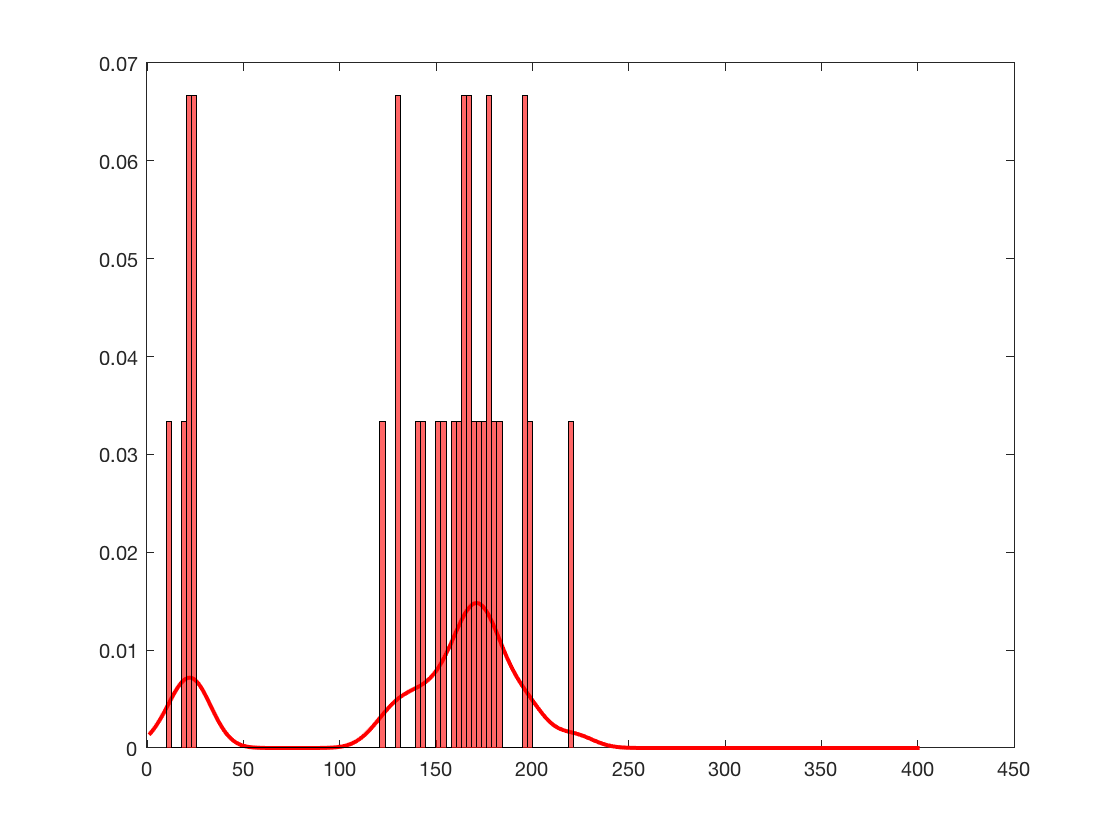

plot(c_pdf,'color','b','LineWidth',2);
%h3 = histogram(control_neg_peaks,60,'facecolor',[0 0 1]);
%h3.Normalization = 'probability';

%


d = SE_neg_peaks;

d_dist = fitdist(d,'Kernel','bandwidth',10);


x = 0:1:400;
d_pdf = pdf(d_dist,x);

figure;
plot(d_pdf,'color','r','LineWidth',2);
hold on
h4 = histogram(SE_neg_peaks,80,'facecolor',[1 0 0]);
h4.Normalization = 'probability';

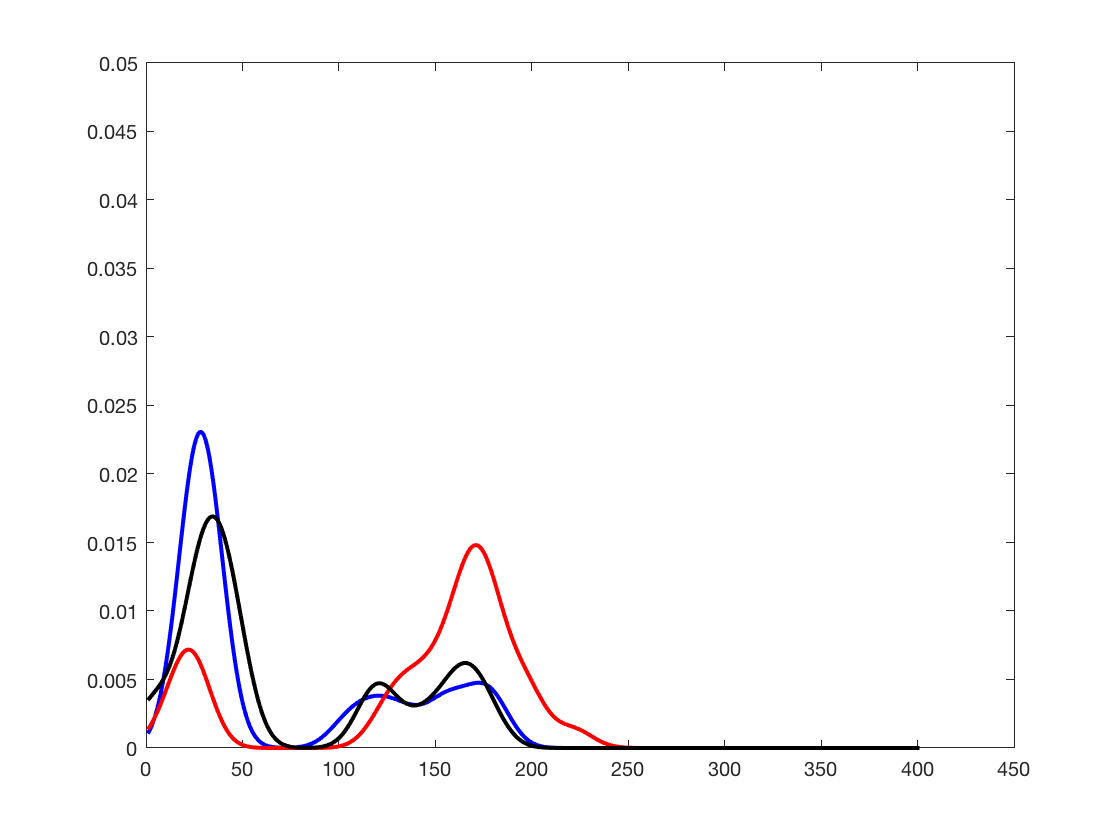


figure;
plot(c_pdf,'color','b','LineWidth',2);
hold on
plot(d_pdf,'color','r','LineWidth',2);
plot(b_pdf,'color','k','LineWidth',2);
ylim([0 0.05])

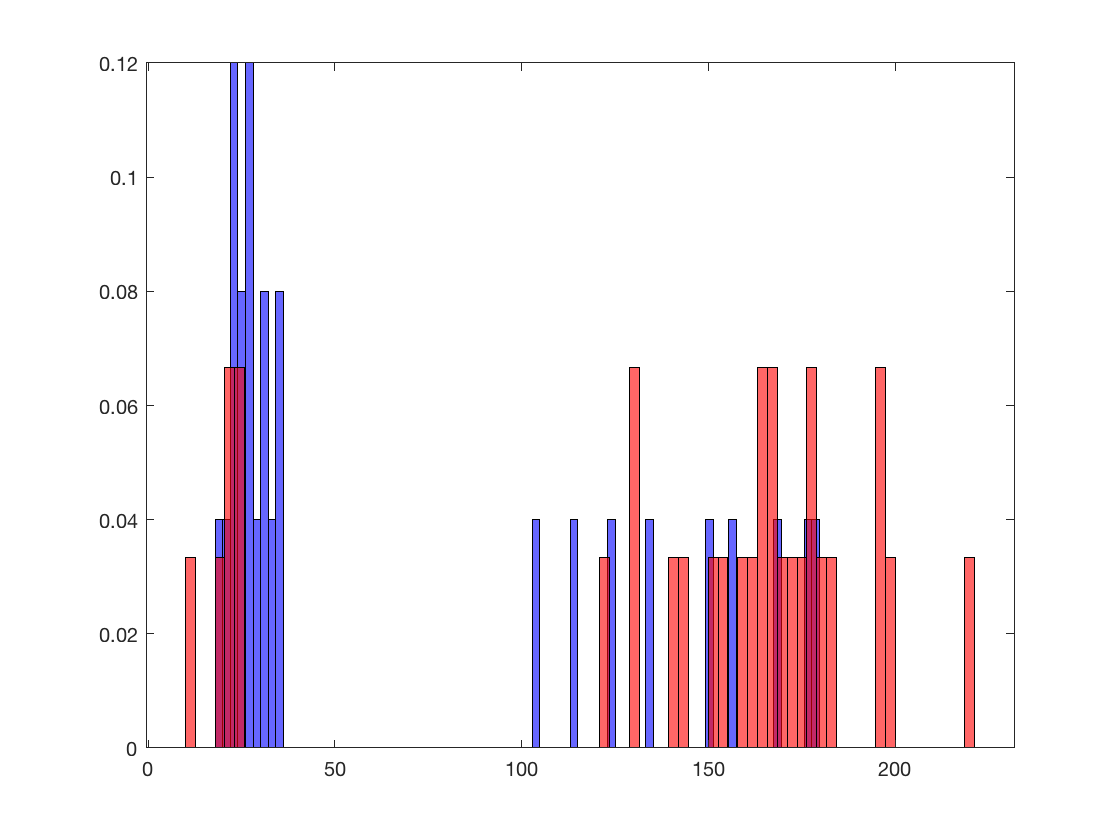


figure;
h3 = histogram(control_neg_peaks,80,'facecolor',[0 0 1]);
h3.Normalization = 'probability'; 
hold on
h4 = histogram(SE_neg_peaks,80,'facecolor',[1 0 0]);
h4.Normalization = 'probability';




 [h,p]=kstest2(c,d)

h = logical
   1


p = 5.5427e-04

 [h,p]=kstest2(c,b)

h = logical
   0


p = 0.2370